**Couplace cinématique-électromyographique**

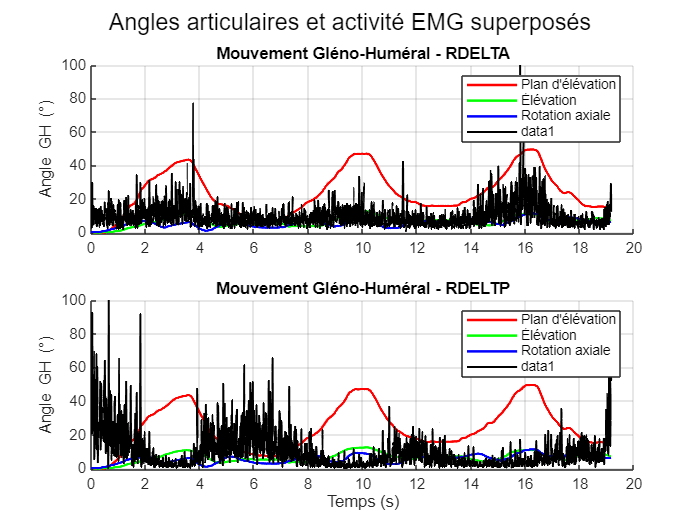

%% -------- Chargement de l'environnement -------- %%
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\3D Kinematics and Inverse Dynamics'));

%% -------- Sélection du mouvement  -------- %%
choice = 4; % Modifier pour changer de mouvement (Analytic 1 à 4)

Subjects = {'MF01'}; 
subj_idx = 1; 

% Définition du fichier
file_names = {... 
    'MF01-MF01-20240101-PROTOCOL01-ANALYTIC1-.c3d', ...
    'MF01-MF01-20240101-PROTOCOL01-ANALYTIC2-.c3d', ...
    'MF01-MF01-20240101-PROTOCOL01-ANALYTIC3-.c3d', ...
    'MF01-MF01-20240101-PROTOCOL01-ANALYTIC4-.c3d'};

chemin_dossier = sprintf('C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s', Subjects{subj_idx});
fichier = fullfile(chemin_dossier, file_names{choice});

% Vérification de l'existence du fichier
if ~isfile(fichier)
    error('Le fichier %s est introuvable.', fichier);
end

% Lecture du fichier C3D
c3dH = btkReadAcquisition(fichier);

%% -------- Extraction des marqueurs -------- %%
markers = btkGetMarkers(c3dH);
nFrames = btkGetLastFrame(c3dH);
fs = 200;
time = (0:nFrames-1) / fs;
time = time(:); % Assure que time est un vecteur colonne

%% -------- Initialisation des matrices pour stocker les angles -------- %%
Angles_GH = zeros(nFrames, 3);
Angles_ST = zeros(nFrames, 3);
Angles_HT = zeros(nFrames, 3);
normalize_vector = @(v) v / norm(v);

%% ======== Extraction des angles d'Euler selon Wu et al. 2005 ======== %%
for i = 1:nFrames
    if any(structfun(@(x) isempty(x), markers)) 
        continue; % Évite les erreurs si des marqueurs sont manquants
    end
    
    % Définition des repères segmentaires
    SJN = markers.SJN(i,:); CV7 = markers.CV7(i,:);
    TV8 = markers.TV8(i,:); SXS = markers.SXS(i,:);
    RSAA = markers.RSAA(i,:); RSRS = markers.RSRS(i,:); RSIA = markers.RSIA(i,:);
    RGH = markers.RSCT(i,:); RHME = markers.RHME(i,:); RHLE = markers.RHLE(i,:);
    
    % Repère du thorax
    Ot = SJN;
    Yt = normalize_vector(mean([SXS; TV8]) - mean([SJN; CV7]));
    Zt = normalize_vector(cross(SJN - CV7, mean([SXS; TV8]) - SJN));
    Xt = normalize_vector(cross(Yt, Zt));
    Rt = [Xt', Yt', Zt'];

    % Repère de la scapula
    Os = RSAA;
    Zs = normalize_vector(RSAA - RSRS);
    Xs = normalize_vector(cross(RSIA - RSAA, RSRS - RSAA));
    Ys = normalize_vector(cross(Xs, Zs));
    Rs = [Xs', Ys', Zs'];

    % Repère de l'humérus
    Rmid_HLE_HME = mean([RHLE; RHME]);
    Oh = RGH;
    Yh = normalize_vector(RGH - Rmid_HLE_HME);
    Xh = normalize_vector(cross(RGH - RHLE, RGH - RHME));
    Zh = normalize_vector(cross(Yh, Xh));
    Rh = [Xh', Yh', Zh'];

    % Correction orthonormalité
    [Ut,~,Vt] = svd(Rt); Rt = Ut * Vt';
    [Us,~,Vs] = svd(Rs); Rs = Us * Vs';
    [Uh,~,Vh] = svd(Rh); Rh = Uh * Vh';

    % Matrices de rotation relatives
    R_HT = Rt' * Rh;
    R_ST = Rt' * Rs;
    R_GH = Rs' * Rh;

    % Extraction des angles d'Euler
    Angles_HT(i,:) = R2mobileYXY_array3(R_HT);
    Angles_ST(i,:) = R2mobileYXZ_array3(R_ST);
    Angles_GH(i,:) = R2mobileYXY_array3(R_GH);
end

%% -------- Filtrage et correction des discontinuités -------- %%
Angles_GH = unwrap(Angles_GH);
Angles_ST = unwrap(Angles_ST);
Angles_HT = unwrap(Angles_HT);

fc = 6;
[b, a] = butter(2, fc / (fs/2), 'low');
Angles_GH = filtfilt(b, a, Angles_GH);
Angles_ST = filtfilt(b, a, Angles_ST);
Angles_HT = filtfilt(b, a, Angles_HT);

% Recentrage des angles pour éliminer un biais initial (ex : commencer à -200°) et recentrer les courbes
Angles_GH(:,3) = Angles_GH(:,3) - mean(Angles_GH(1:10,3));
Angles_ST(:,3) = Angles_ST(:,3) - mean(Angles_ST(1:10,3));
Angles_HT(:,3) = Angles_HT(:,3) - mean(Angles_HT(1:10,3));

Angles_GH(:,2) = Angles_GH(:,2) - mean(Angles_GH(1:10,2));
Angles_ST(:,2) = Angles_ST(:,2) - mean(Angles_ST(1:10,2));
Angles_HT(:,2) = Angles_HT(:,2) - mean(Angles_HT(1:10,2));

Angles_GH(:,1) = Angles_GH(:,1) - mean(Angles_GH(1:10,1));
Angles_ST(:,1) = Angles_ST(:,1) - mean(Angles_ST(1:10,1));
Angles_HT(:,1) = Angles_HT(:,1) - mean(Angles_HT(1:10,1));

% Sélection des muscles à afficher
muscles_R = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RLATD', 'RSERRA'};
muscle_selection = listdlg('PromptString','Sélectionnez les muscles à afficher:', 'SelectionMode','multiple', 'ListString', muscles_R);

if isempty(muscle_selection)
    error('Aucun muscle sélectionné.');
end

selected_muscles = muscles_R(muscle_selection);

fs_emg = 2000;

%% -------- Affichage des angles et EMG superposés -------- %%
figure;
for m = 1:length(selected_muscles)
    muscle_name = selected_muscles{m};
    subplot(length(selected_muscles),1,m); hold on;
    plot(time, rad2deg(Angles_GH(:,1)), 'r', 'LineWidth', 1.5);
    plot(time, rad2deg(Angles_GH(:,2)), 'g', 'LineWidth', 1.5);
    plot(time, rad2deg(Angles_GH(:,3)), 'b', 'LineWidth', 1.5);
    ylabel('Angle GH (\circ)');
    title(['Mouvement Gléno-Huméral - ', muscle_name]);
    legend('Plan d''élévation', 'Élévation', 'Rotation axiale');
    grid on;
    
    % Ajout des signaux EMG
    analogs = btkGetAnalogs(c3dH);
    if isfield(analogs, muscle_name)
        emg_signal = analogs.(muscle_name);
        emg_signal_filtered = filtfilt(b, a, abs(emg_signal));
        emg_rms = sqrt(movmean(emg_signal_filtered.^2, 0.250));
        time_emg = (0:length(emg_signal)-1)/fs_emg;
        plot(time_emg, emg_rms * 100 / max(emg_rms), 'k', 'LineWidth', 1.2);
    else
        warning('Aucune donnée EMG trouvée pour %s.', muscle_name);
    end
end
xlabel('Temps (s)');
sgtitle('Angles articulaires et activité EMG superposés');